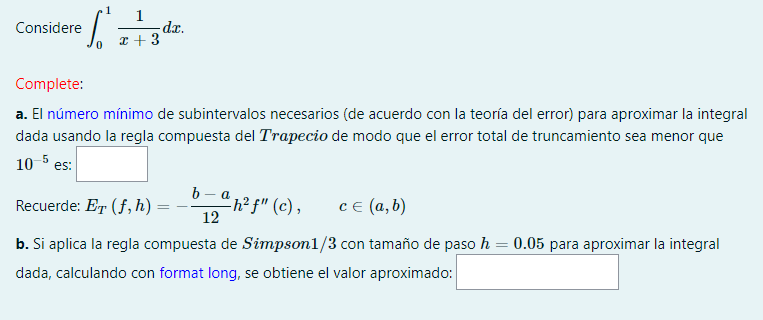

syms x
f = 1/(x+3)

$$f = \frac{1}{x+3}$$

fp = diff(f,2)

$$fp = \frac{2}{{\left(x+3\right)}^{3}}$$

fx = matlabFunction(fp)

fx = function_handle with value:
    @(x)1.0./(x+3.0).^3.*2.0


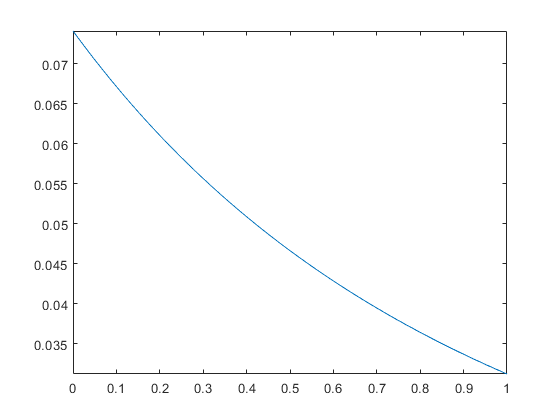

fplot(fx,[0 1])

fx(0)

ans = 0.0741


format long
s= simprl (f, 0, 1, 20)

s =    0.287682074208599


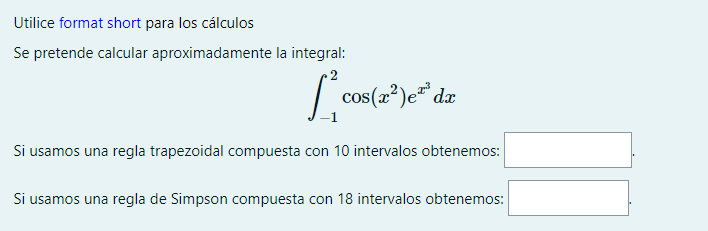

f = @(x) cos(x.^2)*exp(x.^3)

f = function_handle with value:
    @(x)cos(x.^2)*exp(x.^3)


s = traprl (f, -1, 2, 10)

s = -331.3428

s= simprl (f, -1, 2, 18)

s = -223.8841

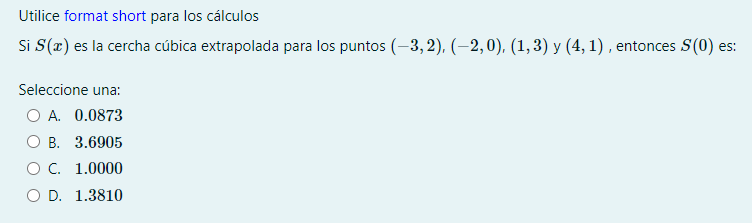

X = [-3 -2 1 4]

X =     -3    -2     1     4


Y = [2 0 3 1]

Y =      2     0     3     1


S=csextrapolado(X,Y)

S =    -0.1468    1.4841   -3.3373    2.0000
   -0.1468    1.0437   -0.8095         0
   -0.1468   -0.2778    1.4881    3.0000


polyval(S(2,:),0+2) %BUENO

ans = 1.3810

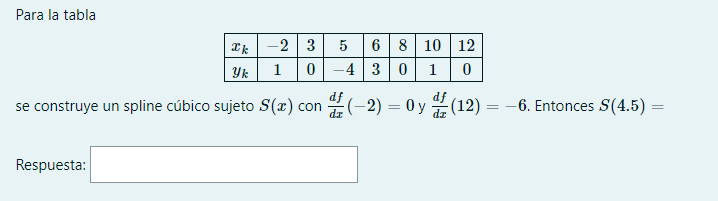

X = [-2 3 5 6 8 10 12]
Y = [1 0 -4 3 0 1 0]
format short
S = csfit (X, Y, 0, -6) % Primero se coloca la derivada en x0 y luego xn (primeras
% derivadas) Misma joda, de S0 a Sn.
polyval(S(2,:),4.5-3) %BUENO

X =     -2     3     5     6     8    10    12


Y =      1     0    -4     3     0     1     0


S =    -0.0820         0    1.8501    1.0000
    1.1901   -1.2300   -4.3002         0
   -3.9707    5.9103    5.0604   -4.0000
    1.3837   -6.0019    4.9689    3.0000
   -0.4168    2.3005   -2.4339         0
   -0.4666   -0.2001    1.7668    1.0000


ans = -5.2014

X = [-3 -2 1 4]

X =     -3    -2     1     4


Y = [2 0 3 1]

Y =      2     0     3     1


format short 
S=csnatural(X,Y)

S =     0.4713         0   -2.4713    2.0000
   -0.2427    1.4138   -1.0575         0
    0.0856   -0.7701    0.8736    3.0000


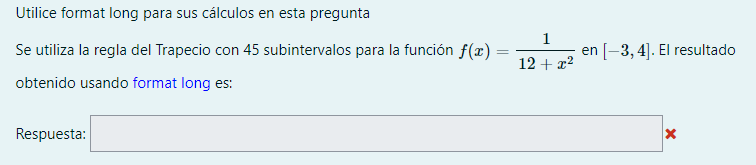


format long
f = @(x) 1./(12+x.^2)

f = function_handle with value:
    @(x)1./(12+x.^2)


a=-3

a =     -3


b=4

b =      4


M=45 %Es el numero de subintervalos. 

M =     10


s = traprl (f, a, b, 45) %BUENO

s =    0.453401829691731


# **SPLINE EXTRAPOLADO**

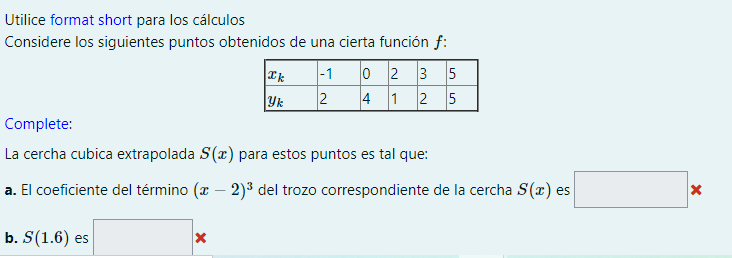

format short
X=[-1 0 2 3 5]

X =     -1     0     2     3     5


Y=[2 4 1 2 5]

Y =      2     4     1     2     5



S=csextrapolado(X,Y)

S =     0.5812   -3.4915    4.9103    2.0000
    0.5812   -1.7479   -0.3291    4.0000
   -0.3932    1.7393   -0.3462    1.0000
   -0.3932    0.5598    1.9530    2.0000



%Evaluar el punto
Eve=polyval(S(2,:),1.6)

Eve = 1.3796


%gráfica

GraficaCercha(X,Y,Se)

Unrecognized function or variable 'Se'.

plot(X0,Eve,'*b')

**FRONTERA COMBINADA (EXTREMOS DERIVADA DIFERENTE)**

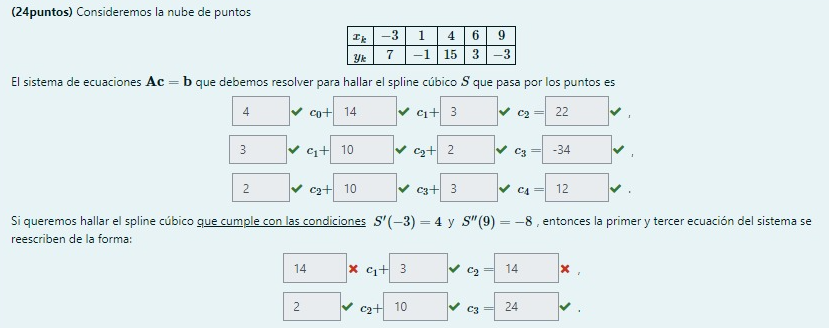

X = [-3 1 4 6 9];
Y = [7 -1 15 3 -3];
[Ac_base, B] = sistemabase(X,Y) % Sistema base

$$Ac\_base = \left(\begin{array}{c} 4\,c_{0}+14\,c_{1}+3\,c_{2}\\ 3\,c_{1}+10\,c_{2}+2\,c_{3}\\ 2\,c_{2}+10\,c_{3}+3\,c_{4} \end{array}\right)$$

B =     22
   -34
    12


[Ac_sujeto, B] = sistemasujeto(X,Y,4,-8) %PRIMERAS DERIVADAS

$$Ac\_sujeto = \left(\begin{array}{c} 12\,c_{1}+3\,c_{2}+9\\ 3\,c_{1}+10\,c_{2}+2\,c_{3}\\ 2\,c_{2}+\frac{17\,c_{3}}{2}+9 \end{array}\right)$$

B =     22
   -34
    12


%Para el problema, me fijo en la primera ecuaciones de 12c1+3c2+9=22

[Ac_curvatura, B] = sistemacurvatura(X,Y,4,-8) %2das DERIVADAS

$$Ac\_curvatura = \left(\begin{array}{c} 14\,c_{1}+3\,c_{2}+8\\ 3\,c_{1}+10\,c_{2}+2\,c_{3}\\ 2\,c_{2}+10\,c_{3}-12 \end{array}\right)$$

B =     22
   -34
    12


% Para el problema nos interesa la ultima ecuaciones 2c2+10c3-12=12

Finalmente los dos sistemas que nos pide el ejercicio son:

1) 12c1+3c2=13

2) 2c2´10c3=24